# Reto Espiras Magneticas

% Oskar Sebastian Ventura Jimenez A01646629
% Bernardo Iñaki Robles Chávez A01646603
% Matías Alfredo Hidalgo Gúzman 01641323
% Juan Pablo Chávez A01646107
% Juan Carlos Arevalo Gomez A01641930

## Variables

clear;
clc;
clf;
nl = 5; % Número de espiras
N = 20; % Puntos por espira
R = 1.5; % Radio de cada espira
sz = 1; % Separación entre espiras en el eje Z
I = 300; % Corriente en amperios
mo = 4*pi*1e-7; % Permeabilidad magnética del vacío
km = mo*I/(4*pi); % Constante de Biot-Savart
rw = 0.2; % Grosor efectivo del alambre
ds = 0.1; % Resolución espacial de la malla en la simulación
dtheta = 2*pi/N; % Incremento angular entre puntos de una espira
ang = 0:dtheta:(2*pi-dtheta); % Vector con los ángulos para una vuelta completa


## Ciclo 1 - Construcción de la espira tridimensional

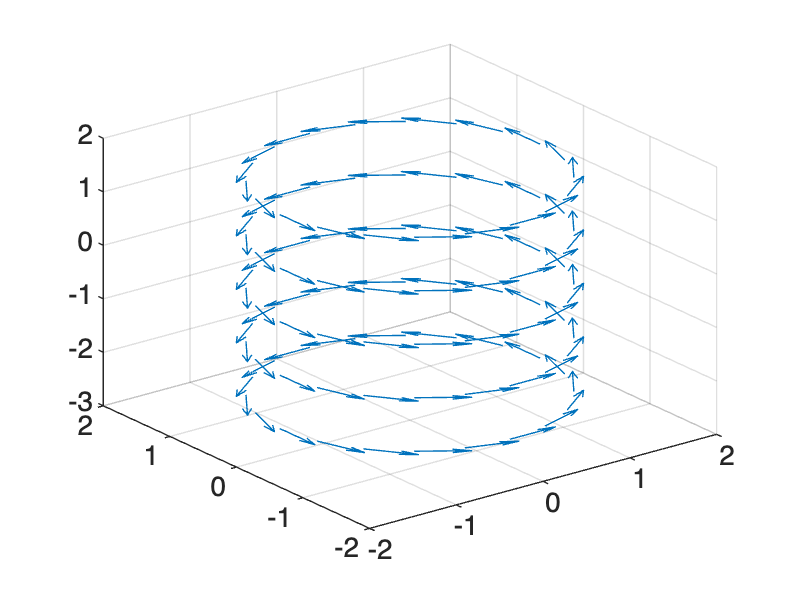

figure(1);
view(3); % Vista 3D
s=1;
for i = 1:nl
    Px(s:s+N-1) = R*cos(ang); % Coordenadas X de la espira i
    Py(s:s+N-1) = R*sin(ang); % Coordenadas Y de la espira i
    Pz(s:s+N-1) = -nl/2*sz+(i-1)*sz;  % Coordenadas Z de la espira i

    dx(s:s+N-1) = -Py(s:s+N-1)*dtheta; % Componente X del vector corriente
    dy(s:s+N-1) = Px(s:s+N-1)*dtheta; % Componente Y del vector corriente
    
    s=s+N; % Actualiza el índice para la siguiente espira
end

dz = zeros(1, N*nl); % Componente Z de la corriente (horizontal)
quiver3(Px,Py,Pz,dx,dy,dz) % Muestra vectores de corriente en 3D

## Ciclo 2 – Cálculo del campo magnético

% Define un vector de posiciones en el eje X desde -5 hasta 5 con paso ds (0.1)
x = -5:ds:5; 
% Usa el mismo vector para el eje Y y Z
y = x; 
z = x; 
% Guarda el número total de puntos en cada eje
Lx = length(x); Ly = length(y); Lz = length(z);
% Estas matrices almacenarán las componentes X, Y y Z del campo magnético total.
dBx = zeros(Lx, Ly, Lz); dBy = dBx; dBz = dBx;

for i = 1:Lx % Recorre posiciones en eje X de la malla
    for j = 1:Ly % Recorre posiciones en eje Y de la malla
        for k = 1:Lz % Recorre posiciones en eje Z de la malla
            for l = 1:nl*N % Recorre segmentos de la corriente
                
                % Vector desde el segmento de corriente l 
                % hasta el punto (x(i), y(j), z(k))
                rx = x(i)-Px(l);
                ry = y(j)-Py(l);
                rz = z(k)-Pz(l);
                
                % Cálculo de la magnitud de r, con un pequeño término rw^2 
                % para evitar singularidades (evitar división por cero)
                r = sqrt(rx^2+ry^2+rz^2+rw^2);
                r3 = r^3;

                % Cálculo del campo magnético diferencial 
                % en cada componente (X, Y, Z)
                dBx(i,j,k) = dBx(i,j,k)+km*dy(l)*rz/r3;
                dBy(i,j,k) = dBy(i,j,k)+km*dx(l)*rz/r3;
                dBz(i,j,k) = dBz(i,j,k)+km*(dx(l)*ry-dy(l)*rx)/r3;

            end
        end
    end
end


## Convertir a plano XZ

Bmag = sqrt(dBx.^2+dBy.^2+dBz.^2); % Magnitud del campo
centery = round(Ly/2); % Selecciona el plano Y medio
Bx_xz = squeeze(dBx(:,centery,:)); % Componente X del campo en plano XZ
Bz_xz = squeeze(dBz(:,centery,:)); % Componente Z del campo en plano XZ
Bxz = squeeze(Bmag(:,centery,:)); % Magnitud del campo en plano XZ


## Graficación

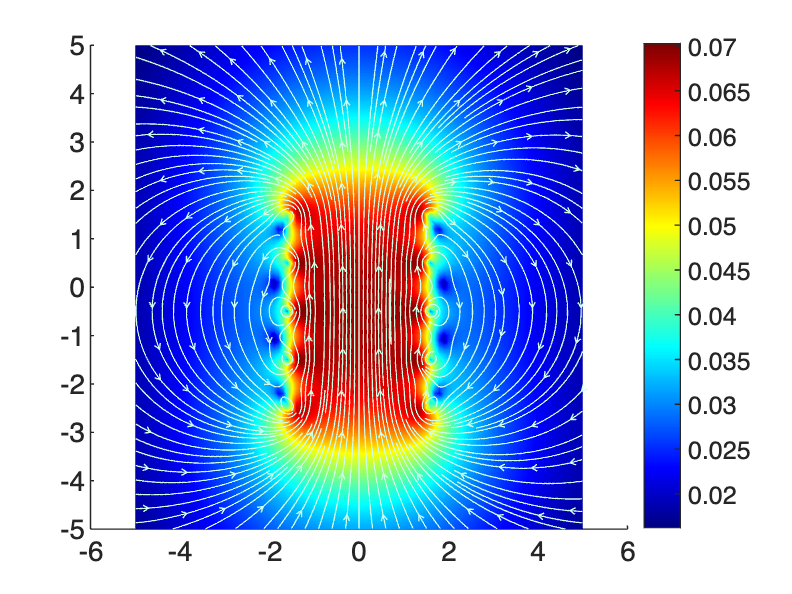

figure(2);
hold on;
pcolor(x,y,(Bxz').^(1/3)); shading interp; colormap jet; colorbar;
h1 = streamslice(x,z,Bx_xz',Bz_xz',3);
set(h1,'Color',[0.8 1 0.9]);